# EE110B Lab 1

# Name: Buddy Ugwumba 

# SID: 862063029

## 1) Use MATLAB to plot the following sequences and discus their periodicity. Choose a proper range of n and a proper pattern for the plots.

###     a)  $x\left\lbrack n\right\rbrack \;=\mathrm{cos}\left(2\pi \frac{7}{3}n\right)$ 

T = 3s

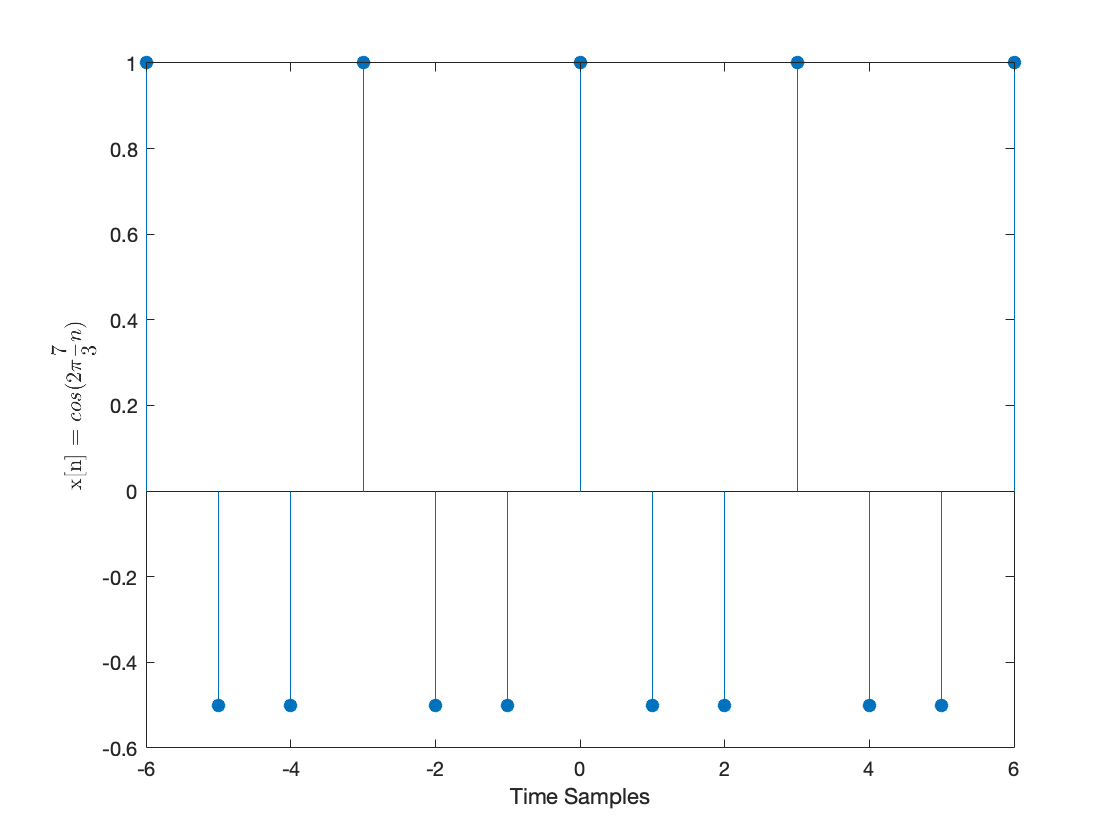

n = -6:1:6;
figure
stem(n, One_a_function_i(n), 'filled');
xlabel('Time Samples');
ylabel('x[n] = $$cos(2\pi\frac{7}{3}n)$$', 'Interpreter', 'latex')

###         
$$x\left\lbrack n\right\rbrack =\mathrm{cos}\left(2\pi \frac{1}{3}n\right)$$


T = 3s

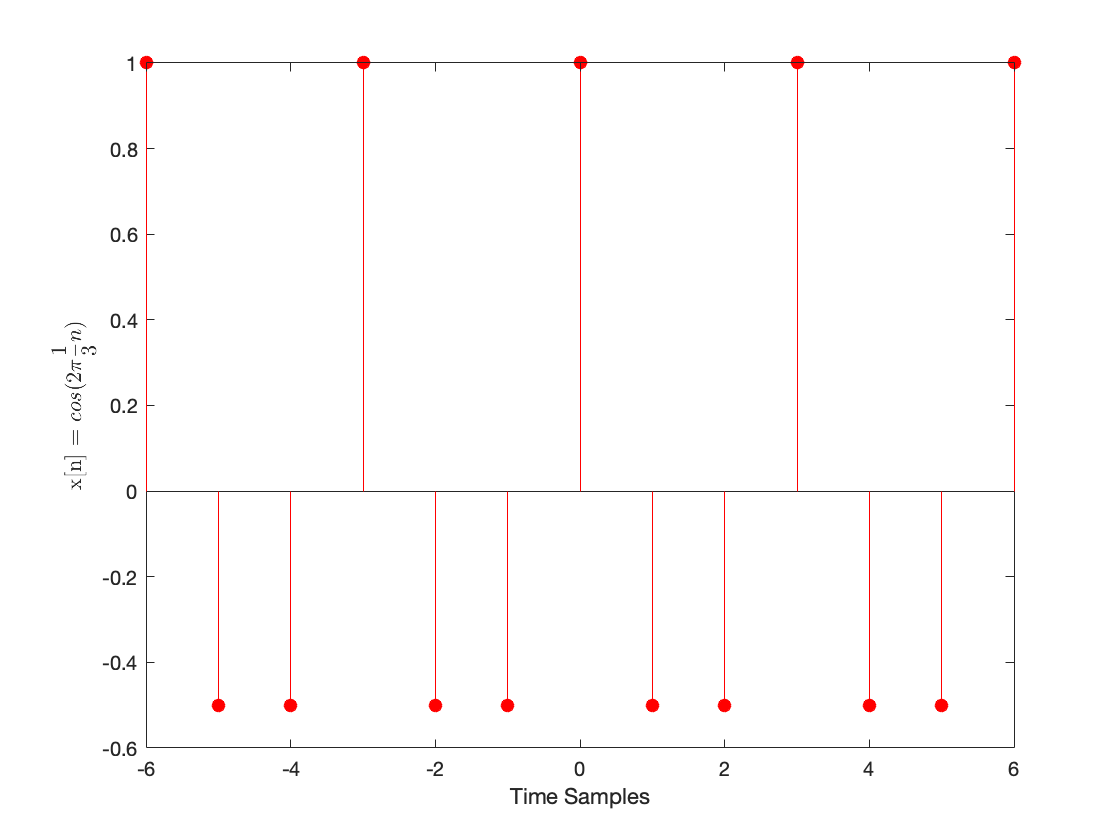

n = -6:1:6;
figure
stem(n, One_a_function_ii(n),'filled','red');
xlabel('Time Samples');
ylabel('x[n] = $$cos(2\pi\frac{1}{3}n)$$', 'Interpreter', 'latex')

###     b) $\mathrm{cos}\left(2\pi \frac{1}{3}n\right)\mathrm{cos}\left(2\pi \frac{4}{5}n\right)$

The trigonometric product identity can be used here

$\mathrm{cos}\alpha *\mathrm{cos}\beta =\frac{\mathrm{cos}\left(\alpha +\beta \right)+\mathrm{cos}\left(\alpha -\beta \right)}{2}$ there fore the system now becomes:


$$\begin{array}{l}
x\left\lbrack n\right\rbrack =\frac{\mathrm{cos}\left(2\pi n\left(\frac{1}{3}+\frac{4}{5}\right)\right)+\mathrm{cos}\left(2\pi n\left(\frac{1}{3}-\frac{4}{5}\right)\right)}{2}\\
=\frac{\mathrm{cos}\left(2\pi \frac{17}{15}n\right)+\mathrm{cos}\left(2\pi \left(-\frac{7}{15}\right)\right)}{2}
\end{array}$$
 

T = 15s

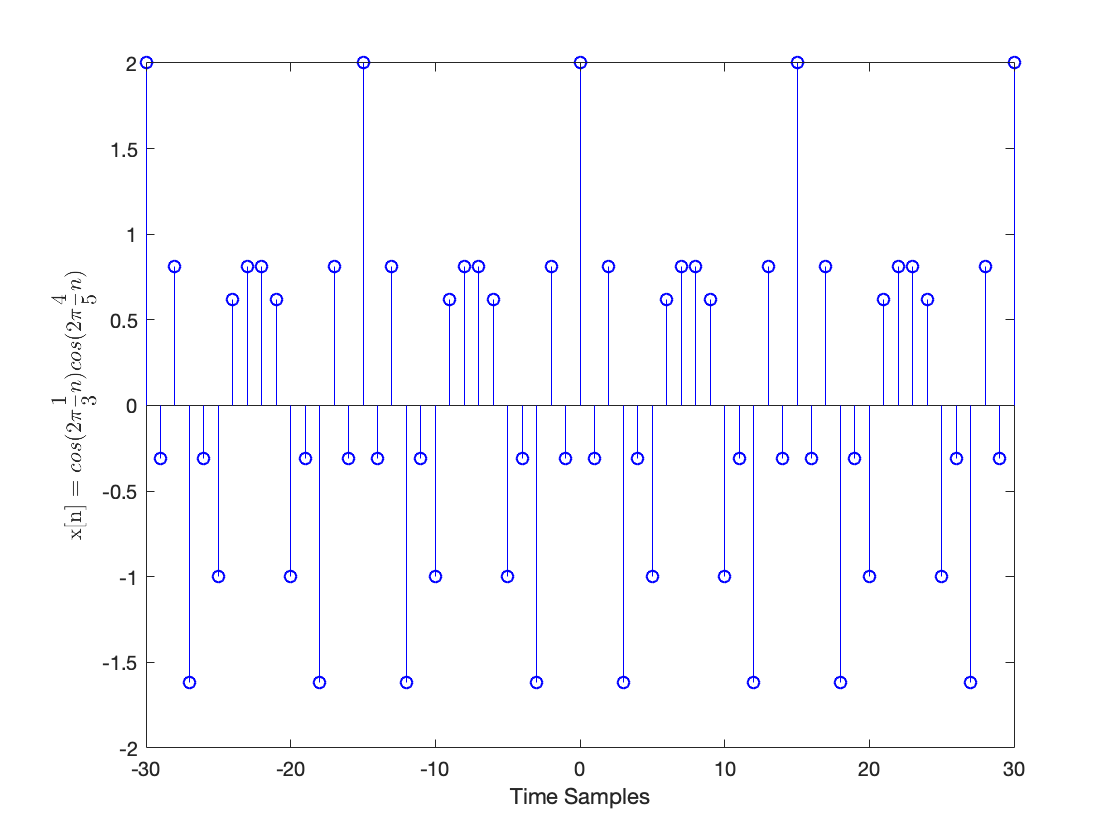

n = -30:1:30;
figure
stem(n, two_function(n), 'blue');
xlabel('Time Samples');
ylabel('x[n] = $$cos(2\pi\frac{1}{3}n)cos(2\pi\frac{4}{5}n)$$', 'Interpreter', 'latex');

I was suprised to find that the period is equal to 3 * 5

###     c) $\mathrm{cos}\left(2\pi \frac{1}{3}n\right)+\mathrm{cos}\left(2\pi \frac{4}{5}n\right)$

            Yes, the period is equal to $q_1 *q_2$. T is found using this equation: $N=m_1 q_1 =m_2 q_2 \to N=\frac{m_1 }{m_2 }=\frac{q_2 }{q_1 }\to N=\frac{m_1 }{m_2 }=\frac{5}{3}=\frac{5}{3}$. Thus $m_{1\;} =5\;$and $q_1 =3$. This makes the period equal to 3*5

T 15s

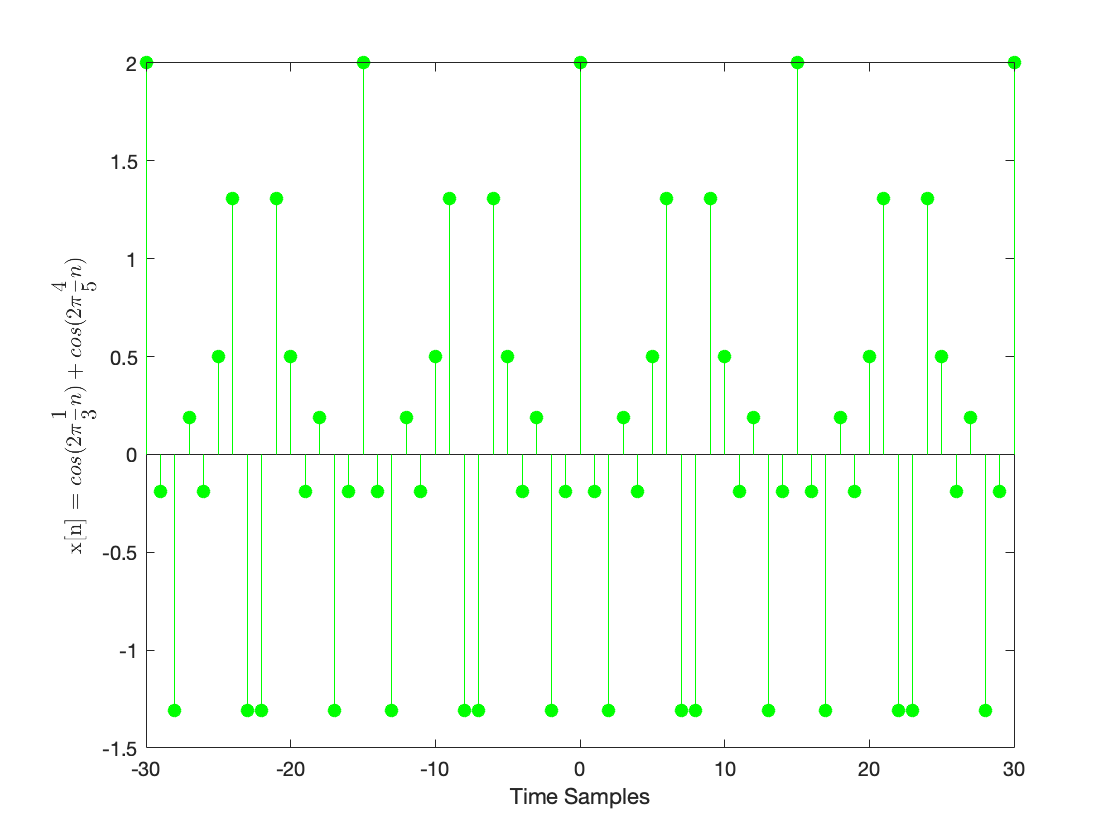

n = -30:1:30;
figure
stem(n, three_function(n), 'filled', 'green');
xlabel('Time Samples');
ylabel('x[n] = $$cos(2\pi\frac{1}{3}n) + cos(2\pi\frac{4}{5}n)$$', 'Interpreter', 'latex');

###     d) $x\left\lbrack n\right\rbrack ={\mathrm{cos}\left(2\pi \frac{1}{3}n\right)}^2$

T = 3s

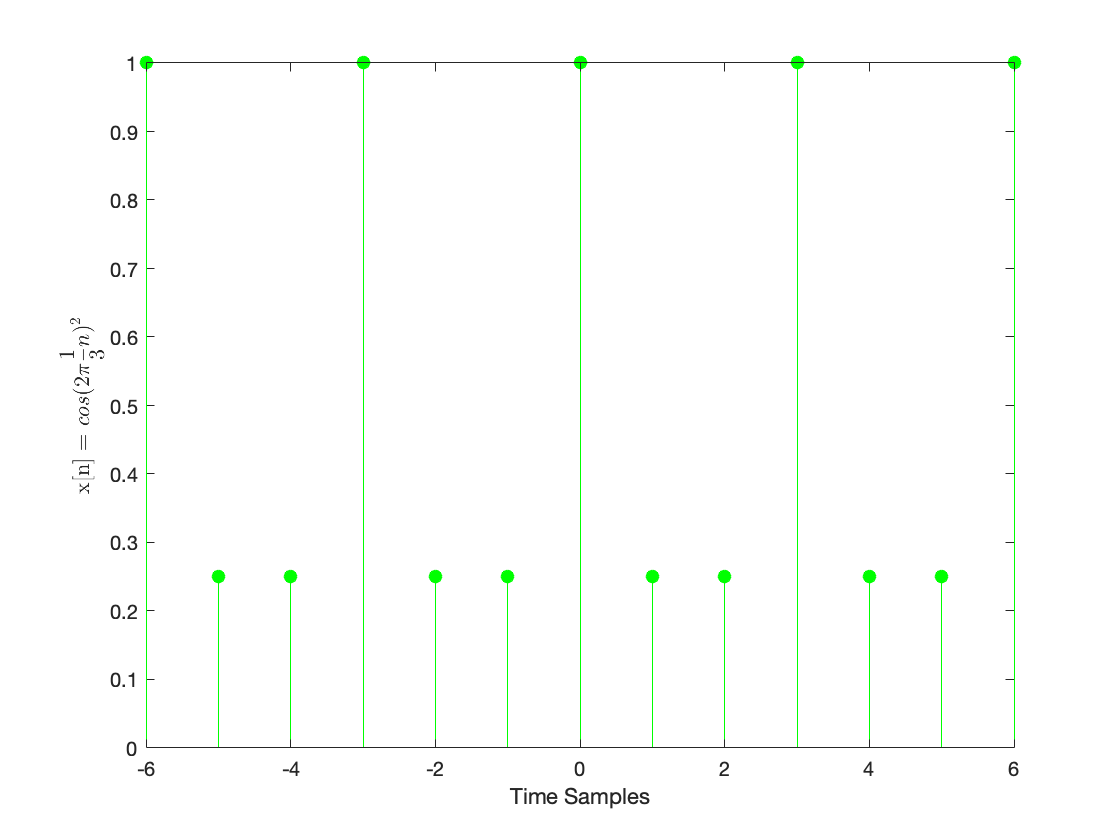

n = -6:1:6;
figure
stem(n, four_function(n), 'filled', 'green');
xlabel('Time Samples');
ylabel('x[n] = $$cos(2\pi\frac{1}{3}n)^{2}$$', 'Interpreter', 'latex');

###     e) $x\left\lbrack n\right\rbrack ={\cos \left(2\pi \frac{1}{3}n\right)}^3$

T = 3s

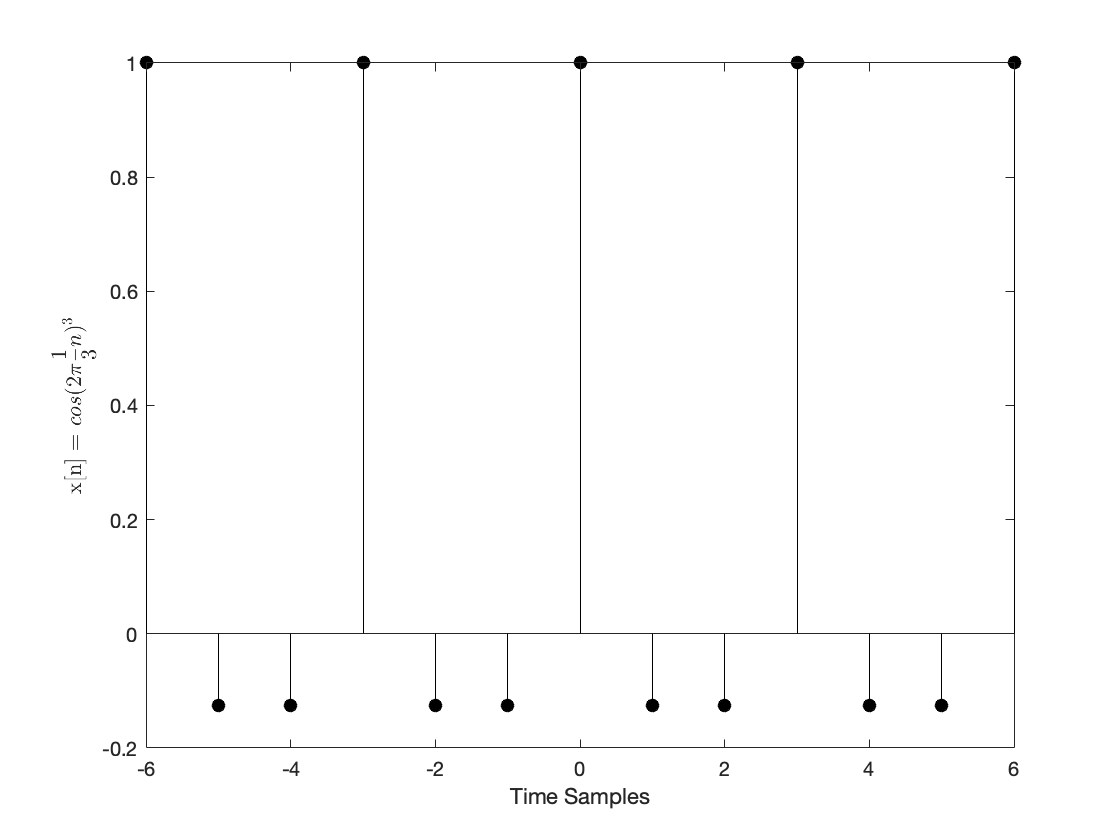

n = -6:1:6;
figure
stem(n, five_function(n), 'filled', 'black');
xlabel('Time Samples');
ylabel('x[n] = $$cos(2\pi\frac{1}{3}n)^{3}$$', 'Interpreter', 'latex');

###     f) $x\left\lbrack n\right\rbrack =\mathrm{cos}\left(2\pi \frac{2}{7}n^2 \right)$

            It's frequency is not changing with time

T = 7s

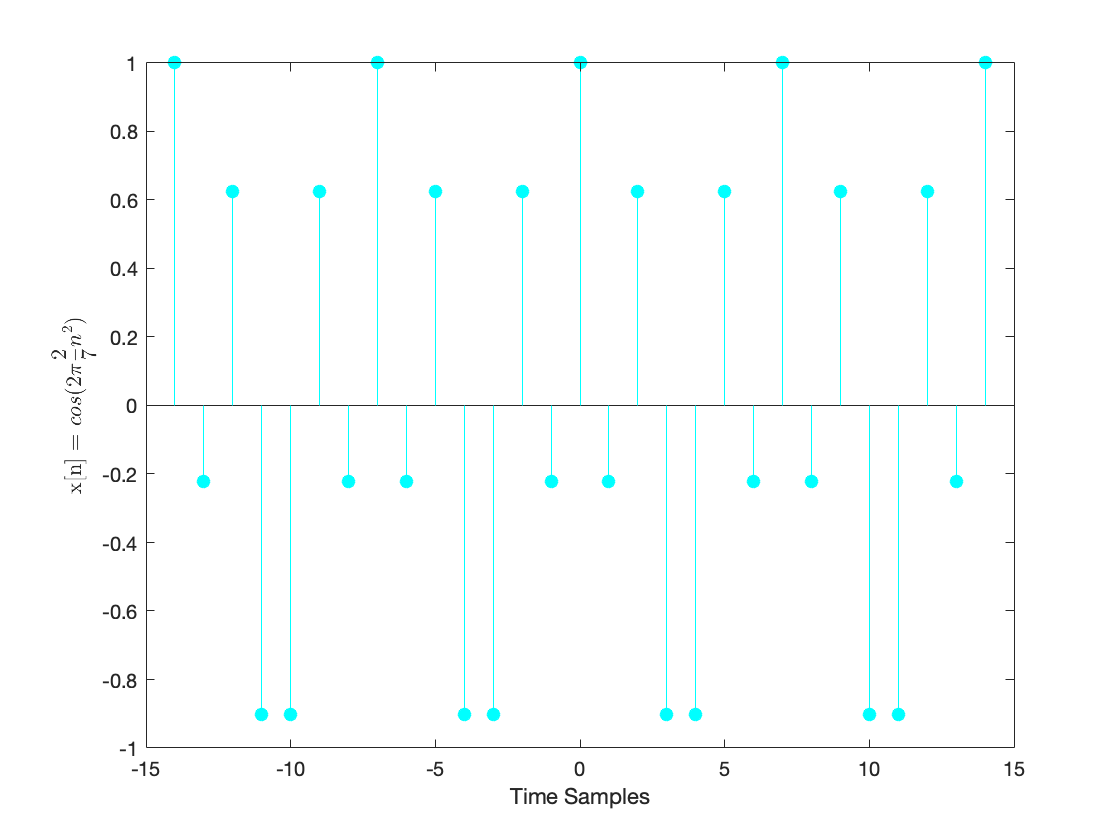

n = -14:1:14;
figure
stem(n, six_function(n), 'filled', 'cyan');
xlabel('Time Samples');
ylabel('x[n] = $$cos(2\pi\frac{2}{7}n^{2})$$', 'Interpreter', 'latex');

###     g) ${0\ldotp 9}^n \mathrm{cos}\left(2\pi \frac{2}{7}n\right)u\left\lbrack n\right\rbrack$

            if $n=\infty$ the value of the sequence is approaching zero because as N grows the denominator grows larger than the numberator

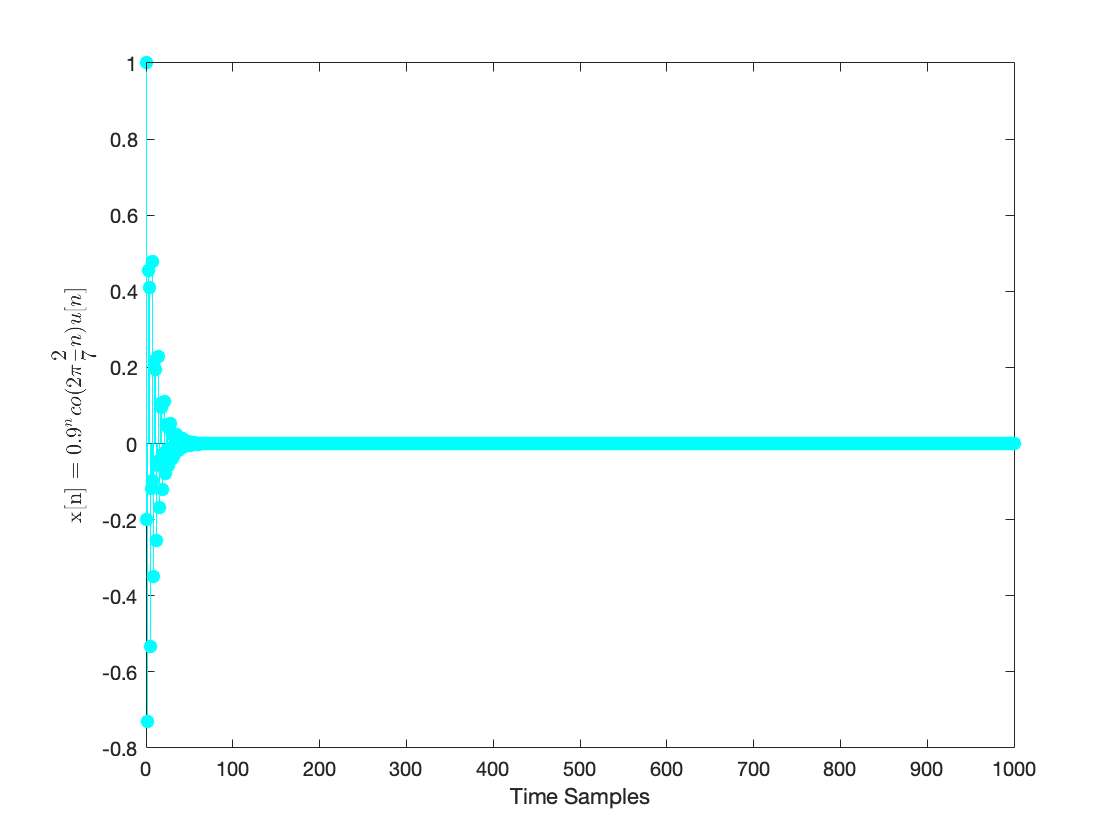

n = 0:1:1000;
figure
stem(n, eleventh_function(n), 'filled', 'cyan');
xlabel('Time Samples');
ylabel('x[n] = $$0.9^{n}co(2\pi\frac{2}{7}n)u[n]$$', 'Interpreter', 'latex');

### h) ${1\ldotp 1}^n \mathrm{cos}\left(2\pi \frac{2}{7}n\right)u\left\lbrack n\right\rbrack$

            if $n=\infty$ the value of the sequencce approaches infinity.

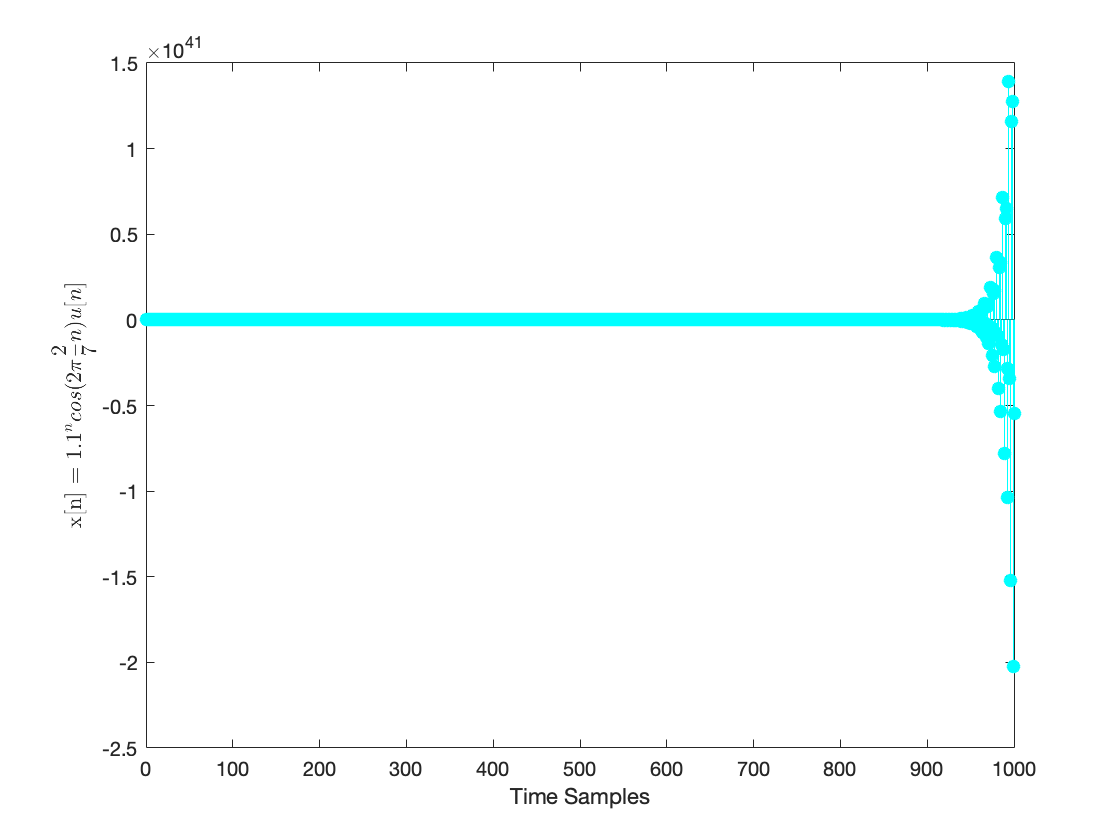

n = 0:1:1000;
figure
stem(n, tweleth_function(n), 'filled', 'cyan');
xlabel('Time Samples');
ylabel('x[n] = $$1.1^{n}cos(2\pi\frac{2}{7}n)u[n]$$', 'Interpreter', 'latex');

## 2) Plot the values of the following complex discrete-time signals on 2-D complex plots

###     a) $x\left\lbrack n\right\rbrack =e^{j\left(2\pi \frac{4}{9}n\;+\;\frac{\pi }{4}\right)}$

            There are nine distinct points on the unit circle becasue nine is the period of the complex function. Moreover, the phase shift is constant

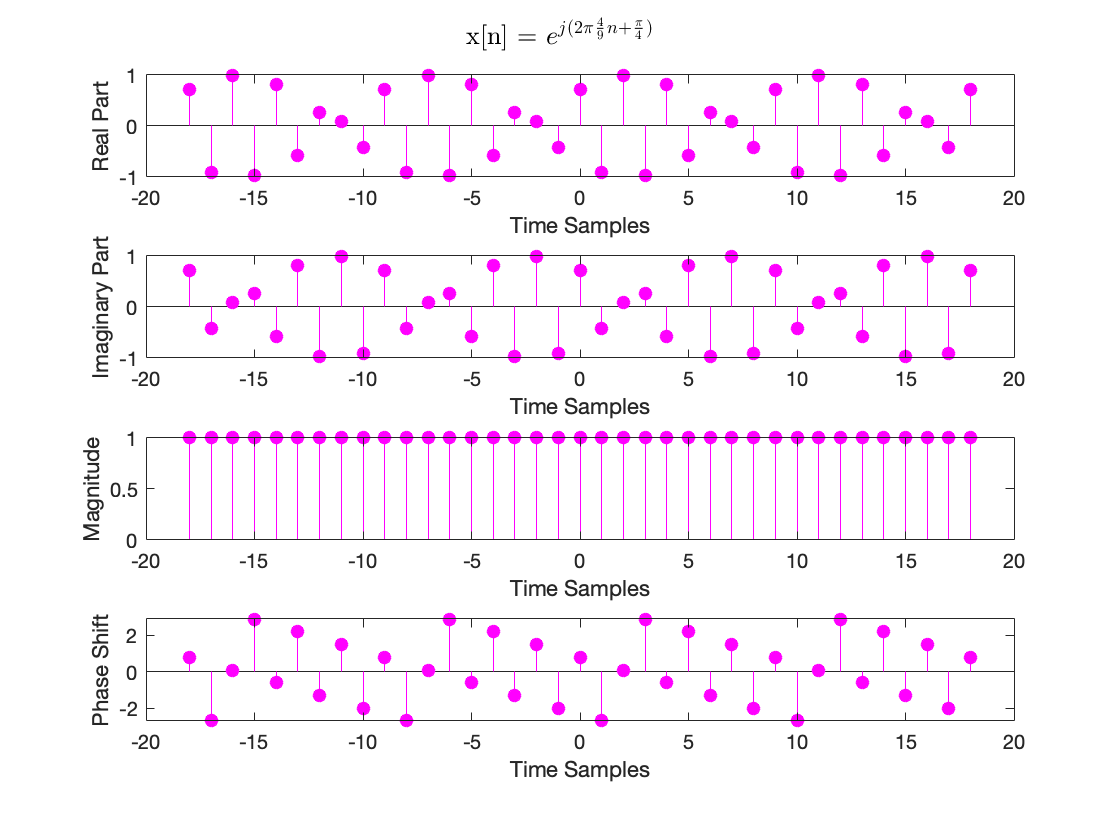

n = -18:1:18;
% For a complex signal, the command 'real' must be used to map the real
% part and the command 'imag' must be used for the imaginary part
subplot(4,1,1);
sgtitle('x[n] = $$e^{j(2\pi\frac{4}{9}n + \frac{\pi}{4})}$$','Interpreter', 'latex');
stem(n, real(seventh_function(n)), 'filled', 'Magenta');
xlabel('Time Samples');
ylabel('Real Part');
subplot(4,1,2);
stem(n, imag(seventh_function(n)), 'filled', 'Magenta');
xlabel('Time Samples');
ylabel('Imaginary Part')
% Now we meed to compute and plot the magnitude
subplot(4,1,3);
stem(n, abs(seventh_function(n)), 'filled', 'Magenta');
xlabel('Time Samples');
ylabel('Magnitude');
% Next we need to plot the phase
subplot(4,1,4);
stem(n, angle(seventh_function(n)), 'filled', 'Magenta');
xlabel('Time Samples');
ylabel('Phase Shift');

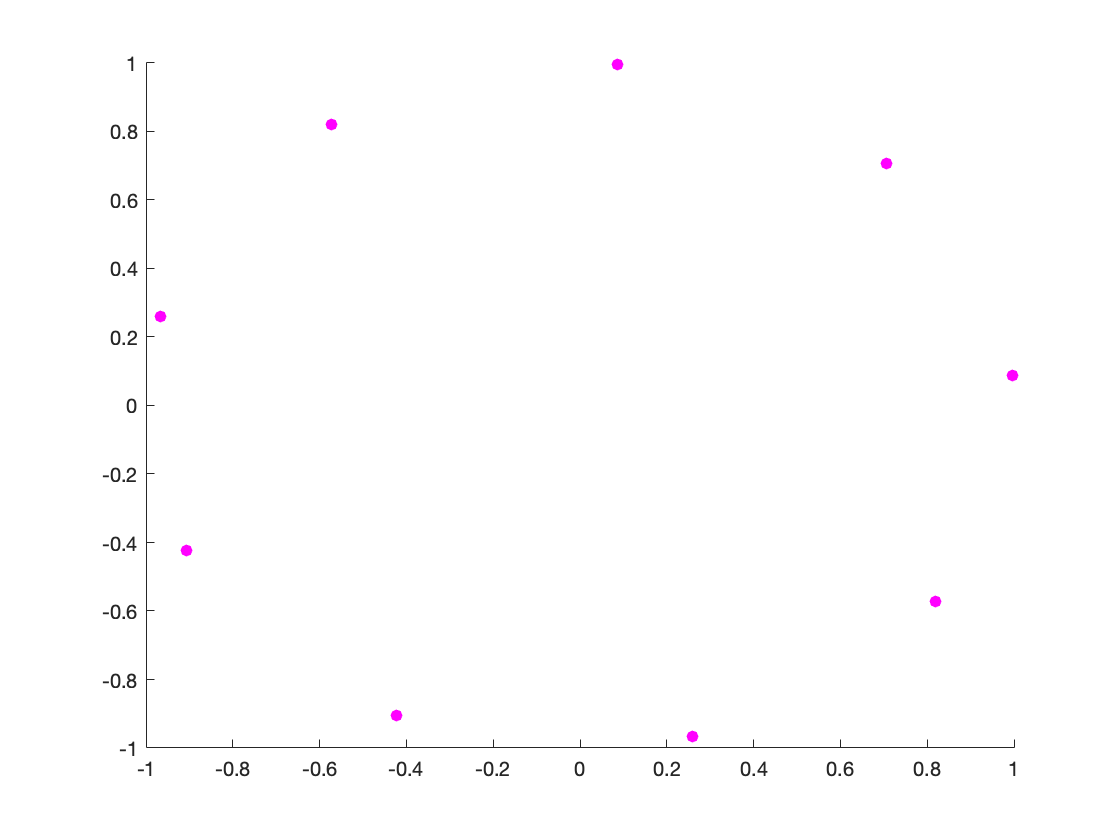

x = -1000:1:1000;
y = seventh_function(x);
figure
scatter(real(y),imag(y), 'filled', 'Magenta');

###     b) $x\left\lbrack n\right\rbrack =e^{j\left(2\pi \frac{4}{9}n^2 \;+\;\frac{\pi }{4}\right)}$

            Ther are four distinct points on the unit circle because n is squared in the complex function. Moreover, the phase shift is constant

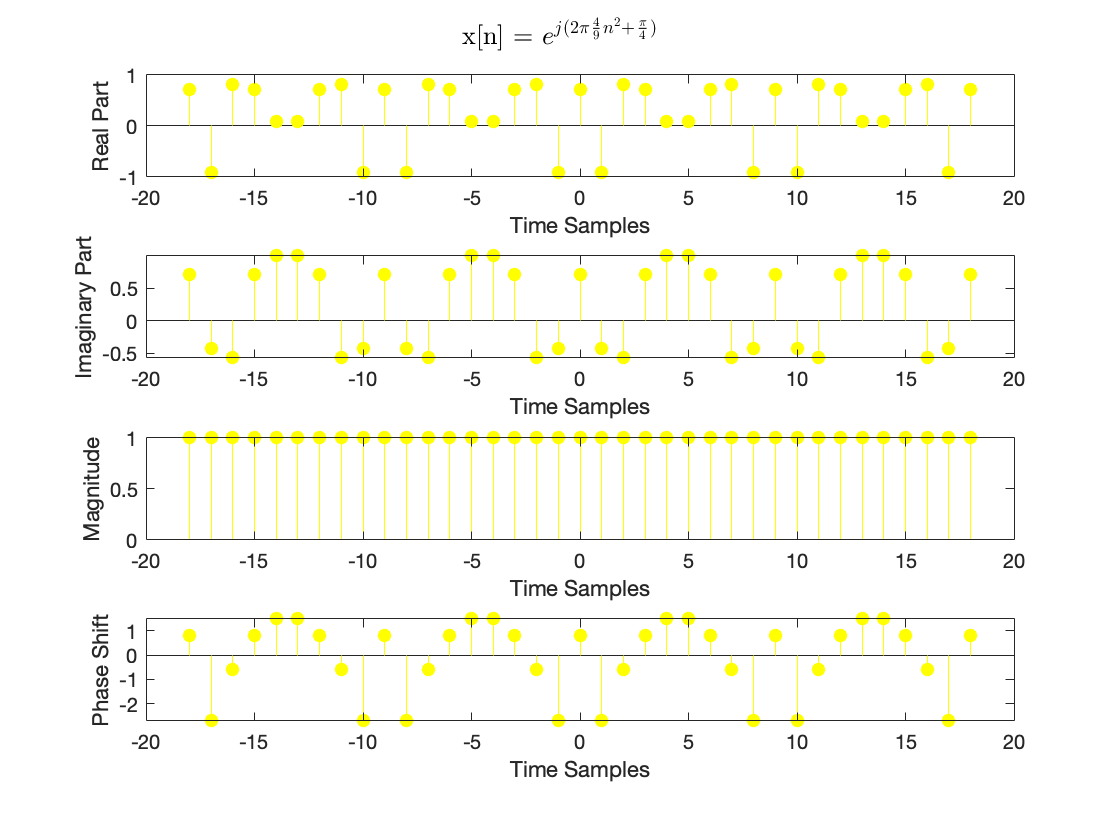

n = -18:1:18;
% For a complex signal, the command 'real' must be used to map the real
% part and the command 'imag' must be used for the imaginary part
subplot(4,1,1);
sgtitle('x[n] = $$e^{j(2\pi\frac{4}{9}n^{2} + \frac{\pi}{4})}$$','Interpreter', 'latex');
stem(n, real(eigth_function(n)), 'filled', 'Yellow');
xlabel('Time Samples');
ylabel('Real Part');
subplot(4,1,2);
stem(n, imag(eigth_function(n)), 'filled', 'Yellow');
xlabel('Time Samples');
ylabel('Imaginary Part')
% Now we meed to compute and plot the magnitude
subplot(4,1,3);
stem(n, abs(eigth_function(n)), 'filled', 'Yellow');
xlabel('Time Samples');
ylabel('Magnitude');
% Next we need to plot the phase
subplot(4,1,4);
stem(n, angle(eigth_function(n)), 'filled', "Yellow");
xlabel('Time Samples');
ylabel('Phase Shift');

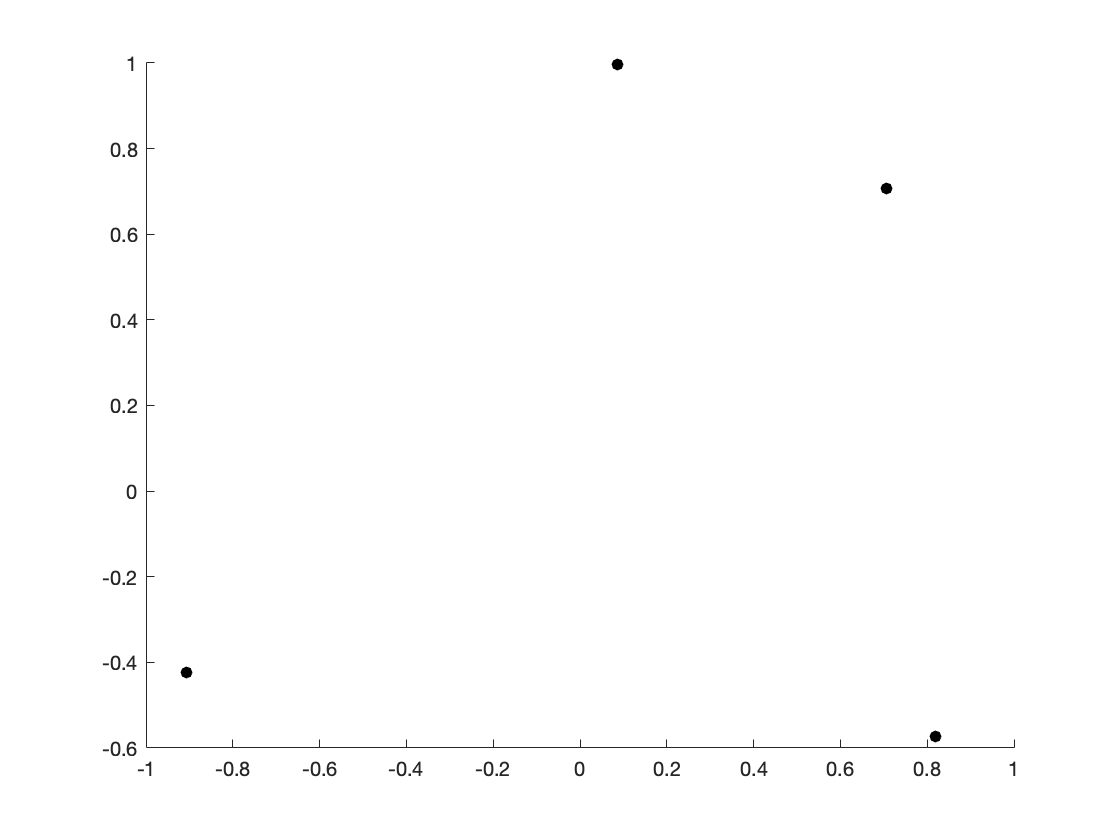

x = -1000:1:1000;
y = eigth_function(x);
figure
scatter(real(y),imag(y),'filled','black');

###   c) $x\left\lbrack n\right\rbrack =e^{j\left(2\pi \frac{4}{3}n\;+\;\frac{\pi }{4}\right)}$

            Ther are three distinct points on the unit circle because three is the period of the complex function. Moreover, the phase shift is constant

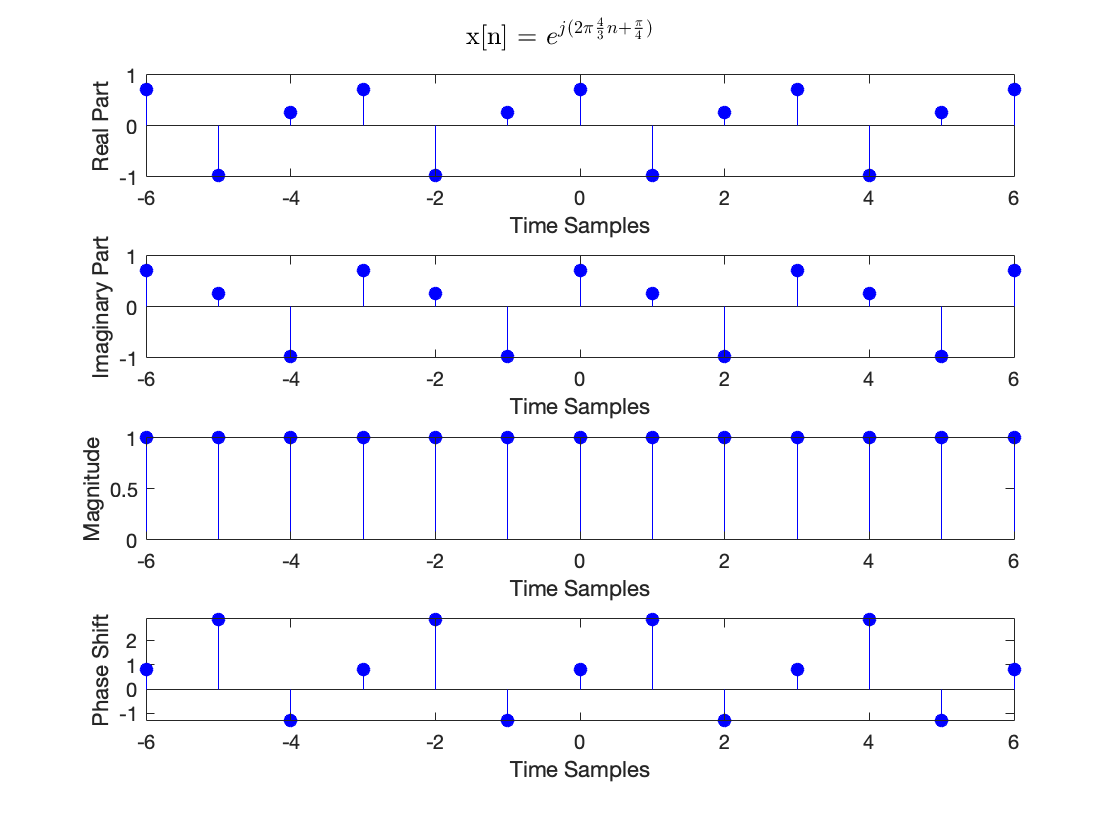

n = -6:1:6;
% For a complex signal, the command 'real' must be used to map the real
% part and the command 'imag' must be used for the imaginary part
subplot(4,1,1);
sgtitle('x[n] = $$e^{j(2\pi\frac{4}{3}n + \frac{\pi}{4})}$$','Interpreter', 'latex');
stem(n, real(ninth_function(n)), 'filled', 'blue');
xlabel('Time Samples');
ylabel('Real Part');
subplot(4,1,2);
stem(n, imag(ninth_function(n)), 'filled', 'blue');
xlabel('Time Samples');
ylabel('Imaginary Part')
% Now we meed to compute and plot the magnitude
subplot(4,1,3);
stem(n, abs(ninth_function(n)), 'filled', 'blue');
xlabel('Time Samples');
ylabel('Magnitude');
% Next we need to plot the phase
subplot(4,1,4);
stem(n, angle(ninth_function(n)), 'filled', 'blue');
xlabel('Time Samples');
ylabel('Phase Shift');

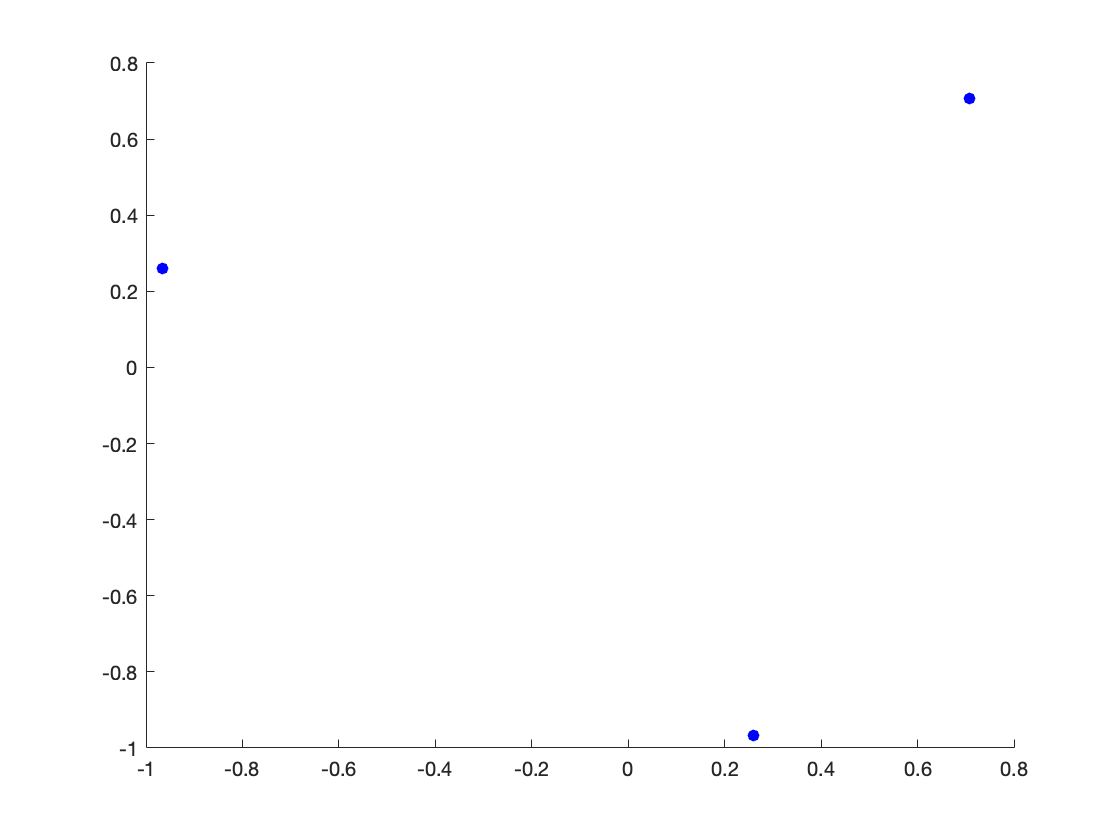

x = -1000:1:1000;
y = ninth_function(x);
figure
scatter(real(y),imag(y),'filled','Blue');

###      d) $x\left\lbrack n\right\rbrack =e^{j\left(\frac{4}{9}n\;+\;\frac{\pi }{4}\right)}$= $e^{j\left(2\pi \frac{4}{18\pi }n\;+\;\frac{\pi }{4}\right)}$

            There are infinitely many distinct points on the unit circle because the signal is not periodic.

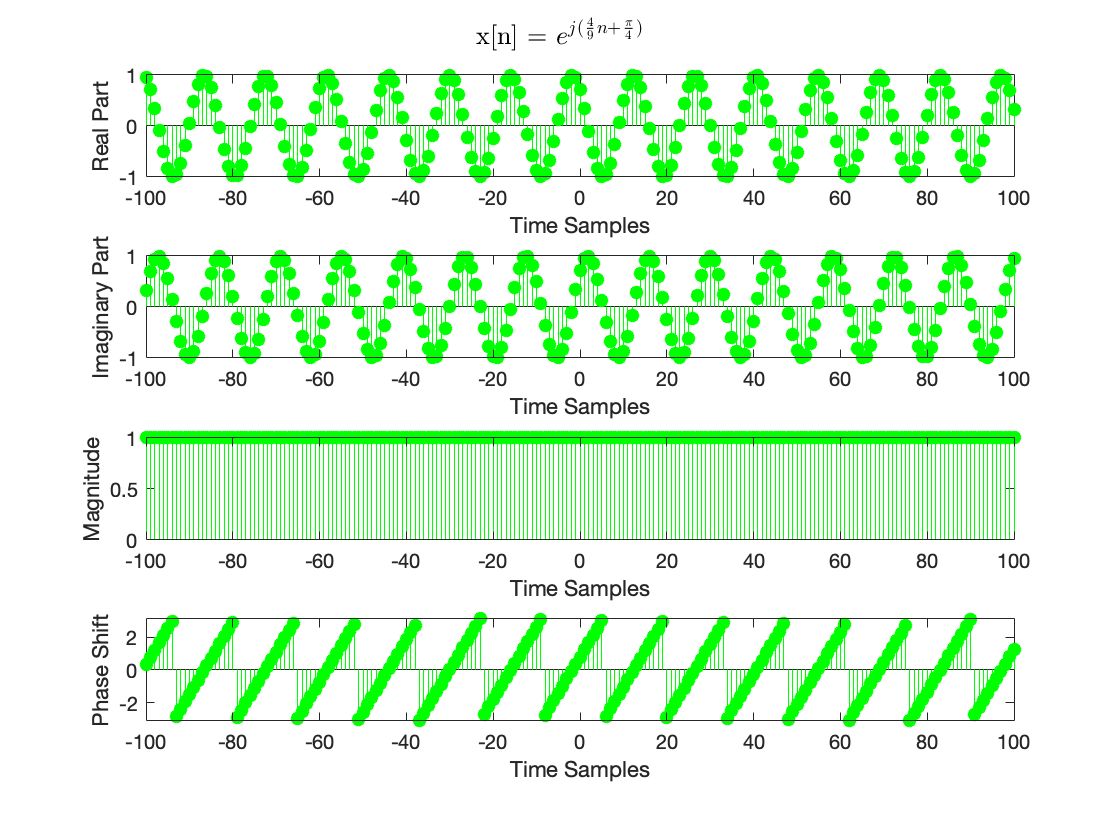

n = -100:1:100;
% For a complex signal, the command 'real' must be used to map the real
% part and the command 'imag' must be used for the imaginary part
subplot(4,1,1);
sgtitle('x[n] = $$e^{j(\frac{4}{9}n + \frac{\pi}{4})}$$','Interpreter', 'latex');
stem(n,real(tenth_function(n)),'filled', 'green');
xlabel('Time Samples');
ylabel('Real Part');
subplot(4,1,2);
stem(n, imag(tenth_function(n)),'filled','green');
xlabel('Time Samples');
ylabel('Imaginary Part')
% Now we meed to compute and plot the magnitude
subplot(4,1,3);
stem(n, abs(tenth_function(n)), 'filled','green');
xlabel('Time Samples');
ylabel('Magnitude');
% Next we need to plot the phase
subplot(4,1,4);
stem(n, angle(tenth_function(n)), 'filled','green');
xlabel('Time Samples');
ylabel('Phase Shift');

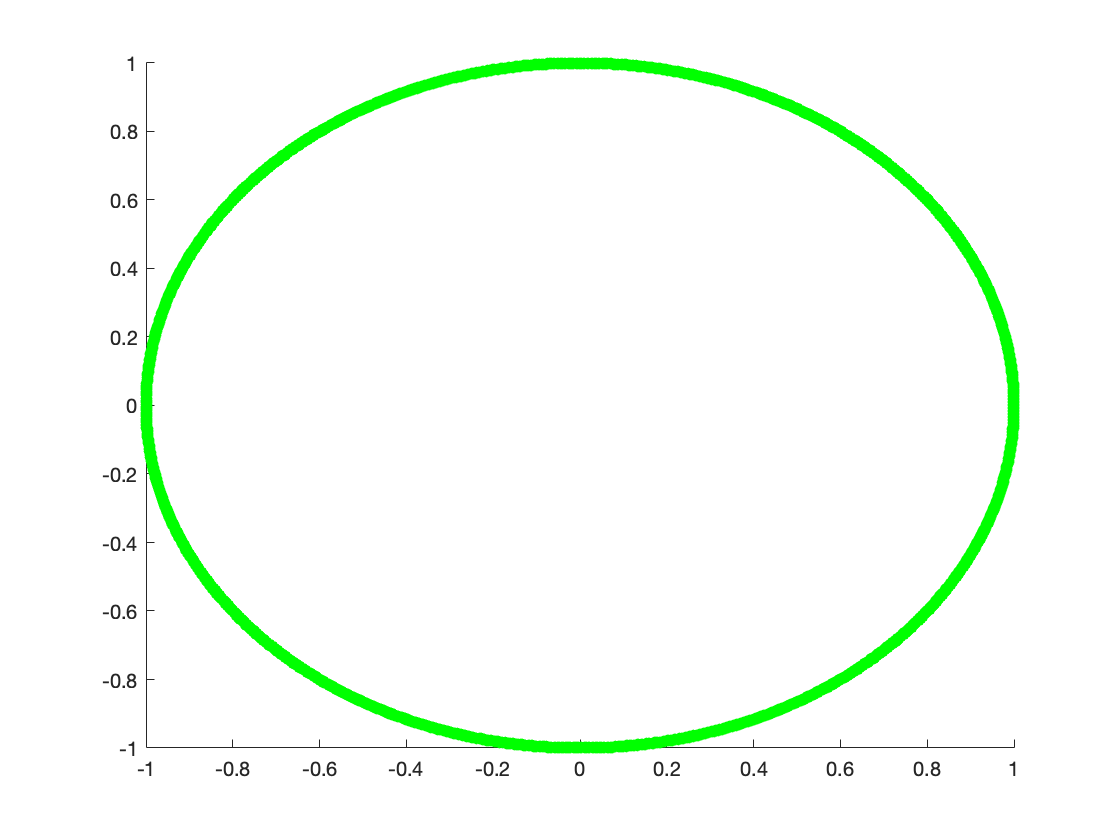

x = -1000:1:1000;
y = tenth_function(x);
figure
scatter(real(y),imag(y), 'filled', 'green');

function c = three_function(n)
c = cos(2*pi*(1/3)*n) + cos(2*pi*(4/5)*n);
end

function d = two_function(n)
d = cos(2*pi*(17/15)*n) + cos(2*pi*(-7/15)*n);
end

function e = four_function(n)
e = cos(2*pi*(1/3)*n).^(2);
end

function f = five_function(n)
f = cos(2*pi*(1/3)*n).^(3);
end

function f = six_function(n)
f = cos(2*pi*(2/7)*n.^(2));
end

function f = seventh_function(n)
f = exp(1i*(2*pi*(4/9)*n + (pi/4)));
end

function g = eigth_function(n)
g = exp(1i*((2*pi*(4/9)*n.^(2)) + (pi/4)));
end

function h = ninth_function(n)
h = exp(1i*((2*pi*(4/3)*n + (pi/4))));
end

function i = tenth_function(n)
i = exp(1i*((4/9)*n + (pi/4)));
end

function j = eleventh_function(n)
j = 0.9.^(n).*cos(2*pi*(2/7)*n);
end

function k = tweleth_function(n)
k = 1.1.^(n).*cos(2*pi*(2/7)*n);
end